## 分类算法

山东理工大学 数学院  周世祥 shixiangbupt@qq.com

### 什么是分类？

分类算法研究如何自动学习根据观测到的数据做出准确的预测。

分类学习的第一步是对数据集进行标注，预定义标签label。

对每个样本的特征向量都标注一个预先定义好的标签，用于表示这个样本所属类别。

二分类问题：只有两个类别

从样本的特征向量到标签的映射函数称为分类器，classifer

回归问题的输出是连续值

分类问题的输出是离散值

学习输入数据和输出数据之间映射关系。

1、决策树

[https://ww2.mathworks.cn/help/stats/classification-trees.html?s_tid=CRUX_lftnav](https://ww2.mathworks.cn/help/stats/classification-trees.html?s_tid=CRUX_lftnav)

[https://ww2.mathworks.cn/help/stats/decision-trees.html](https://ww2.mathworks.cn/help/stats/decision-trees.html)

matlab官方案例

一系列判断结果及其判断条件的图形化展示，树形结构，节点(变量)，分支：取值范围，叶节点：分类结果。

### 决策树的优缺点：

决策树与KNN的共同点，二者都采取“分而治之”的策略，将特征空间分割为若干区域，利用近邻进行预测。决策树利用了信息论的知识，更具智慧，应用到高维空间中不容易收噪声影响。

如果真实模型或决策边界为线性，则线性模型预测效果一般优于决策树，反之，决策树预测效果更好。

X=rand(100,2);
Y=(X(:,1)<0.3 | X(:,2)>0.6);
SimpleTree=fitctree(X,Y)

SimpleTree =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 100


  Properties, Methods


view(SimpleTree)


分类的决策树
1  if x2<0.600159 then node 2 elseif x2>=0.600159 then node 3 else true
2  if x1<0.297807 then node 4 elseif x1>=0.297807 then node 5 else false
3  class = true
4  class = true
5  class = false



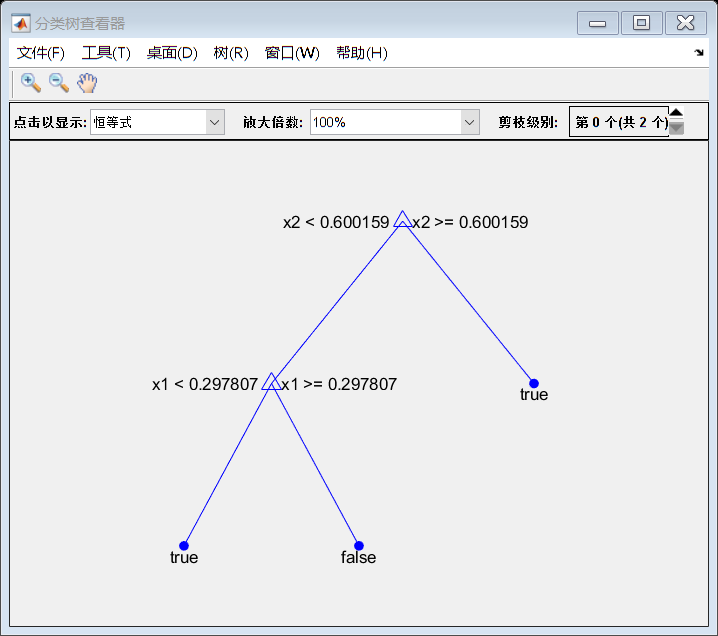

view(SimpleTree,'mode','graph')

训练好的决策树可以用来对未经标注的数据进行分类。

使用决策树对样本进行分类的过程如下：

- 从根节点开始

- 根据当前节点的名称，在待分类样本特征向量中选择对应变量的值

- 根据当前节点的分支的定义域及待分类样本对应的值，选择待分类样本所属的分支

- 根据分支到达下一节点，如果此节点是叶节点，则算法结束并返回叶节点的值；如果此节点是节点，则回到第二步继续执行。

一棵树有多少叶节点就有多少条规则，用Iris Flower数据集，3种iris花，每种有50个样本，每个样本的特征向量包含4个特征值：萼片长度，萼片宽度，花瓣长度，花瓣宽度

类别标签为：setosa，Versicolur，virginica，

%FisherIris dataset
load fisheriris
tabulate(species)%变量的统计数据

       Value    Count   Percent
      setosa       50     33.33%
  versicolor       50     33.33%
   virginica       50     33.33%


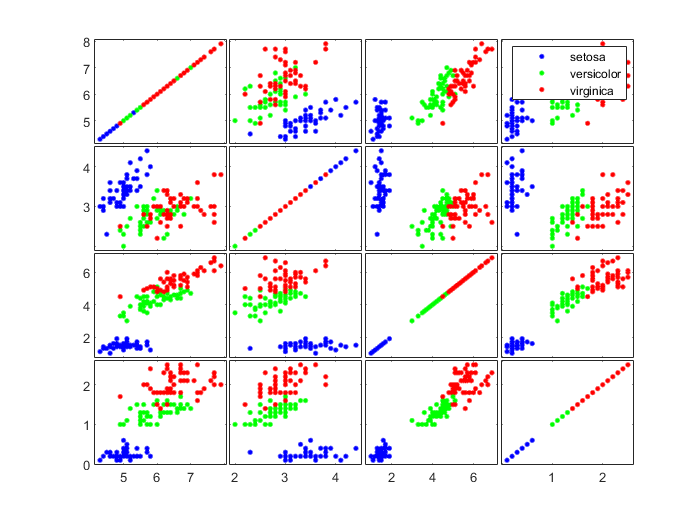

% gplotmatrix(a,b,group) 
% 语法a(m*n1),b(m*n2)表示的是全部样本m个的特征矩阵。

gplotmatrix(meas, meas, species);

% 根据means特征矩阵及species中标注的类别标签绘制散点图


setosa类与其他类非常不同。其余两类在散点图中存在大量重合。

仔细观测根据花瓣特征值(长度和宽度)绘制的散点图，可以使用函数gscatter()，meas变量的第3列表示花瓣长度，第4列为花瓣宽度，gscatter()函数的第三个参数为类别标签。

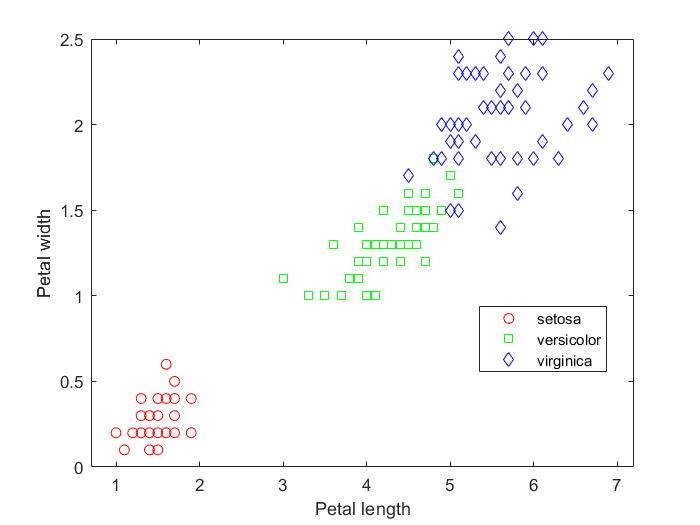

gscatter(meas(:,3), meas(:,4), species,'rgb','osd');
xlabel('Petal length');
ylabel('Petal width');

可见根据花瓣的特征值对花朵进行分类是可行的，使用函数fitctree()对整个特征值矩阵构建决策树。这个函数返回基于特征矩阵和标签向量构建的二叉树决策树。

ClassTree= fitctree(meas,species);
view(ClassTree)


分类的决策树
1  if x3<2.45 then node 2 elseif x3>=2.45 then node 3 else setosa
2  class = setosa
3  if x4<1.75 then node 4 elseif x4>=1.75 then node 5 else versicolor
4  if x3<4.95 then node 6 elseif x3>=4.95 then node 7 else versicolor
5  class = virginica
6  if x4<1.65 then node 8 elseif x4>=1.65 then node 9 else versicolor
7  class = virginica
8  class = versicolor
9  class = virginica



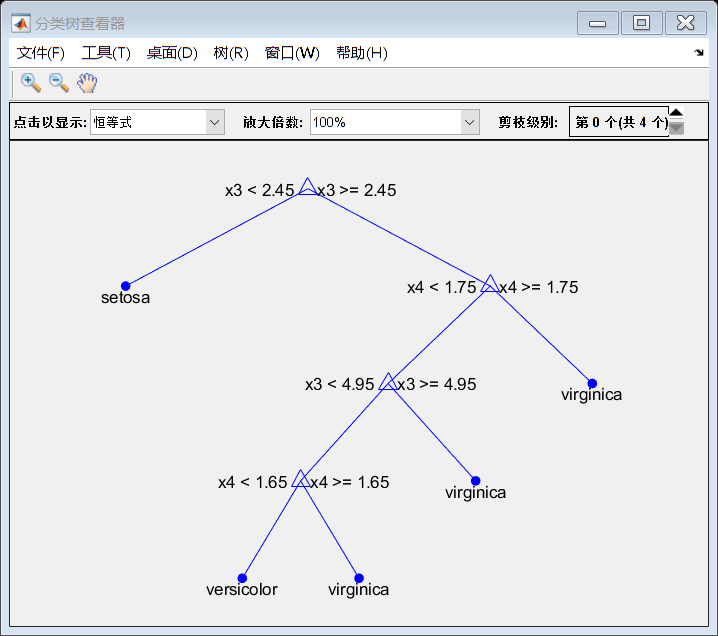

view(ClassTree,'mode','graph') %树状图

%优化生成的二叉树中只使用了x3,x4两个特征值，即花瓣的宽度和长度

待分类样本的特征向量如下：

MeasNew= [5.9 3.2 1.3 0.25];

预测

predict(ClassTree,MeasNew)

ans = 1×1 cell 数组
    {'setosa'}


计算训练误差：衡量决策树对待分类样本所预测的分类标签与数据集中真实标签间差距的指标，初步表达模型性能优劣。

resuberror = resubLoss(ClassTree)

resuberror =    0.020000000000000


预测误差：对模型的泛化能力进行评估，使用交叉验证进行验证。

训练误差和混淆矩阵只能衡量模型训练集拟合程度的好坏，不能衡量任何相关模型的泛化能力。简单地将数据集分训练集和测试集两部分，并使用测试集来衡量模型的泛化能力并不是十分精确，具有鲁棒性的方法，单一地划分训练集和测试集很可能过于复杂或简单的样本集中在任意数据集中，造成预测误差过大或过小。

因此，模型在不同训练集，预测集上进行多次训练，预测，能够更具有鲁棒性，精确衡量模型泛化能力，但这要求大量的数据通过使用交叉验证，在少量数据集中也可以实现上述目标。

将整个数据集分成k份，每次验证都抽取一份作验证集，其余作为训练集，这个过程被重复k次，每个样本都至少被训练并预测过一次。

matlab中对交叉验证的默认设置为10折交叉验证。

cvrtree = crossval(ClassTree)%返回交叉验证模型

cvrtree =   classreg.learning.partition.ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'}
           ResponseName: 'Y'
        NumObservations: 150
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'setosa'  'versicolor'  'virginica'}
         ScoreTransform: 'none'


  Properties, Methods


cvloss = kfoldLoss(cvrtree)%计算整个交叉验证的测量误差

cvloss =    0.073333333333333


分类的评价

1、评价指标（以二元分类为例）

- True Positive(TP)：指模型预测为正(1)的，并且实际上也的确是正(1)的观测对象的数量

- True Negative(TN)：指模型预测为负(0)的，并且实际上也的确是负(0)的观测对象的数量

- False Positive(FP)：指模型预测为正(1)的，但实际上是负(0)的观测对象的数量

- False Negative(FN)：指模型预测为负(0)的，但实际上是正(1)的观测对象的数量

二类问题的混淆矩阵

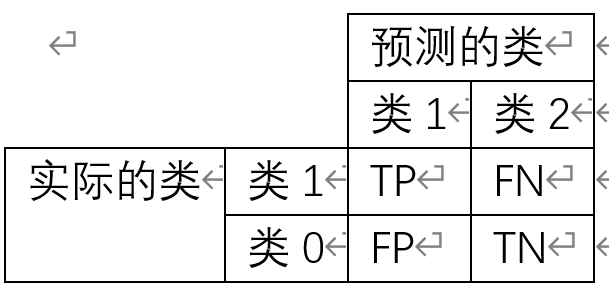

基于上述基本定义有以下评价指标：

- Accuracy rate 正确率：模型总体正确率，识别1和0的对象数量与预测对象总数的比值，公式为：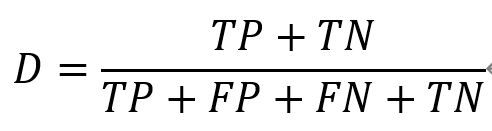

- Error rate：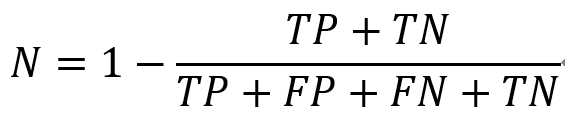hu

- Sensitivity：灵敏性，又称击中率或真阳率，模型正确识别为正1的对象占全部观测对象中实际为正1的对象数量比值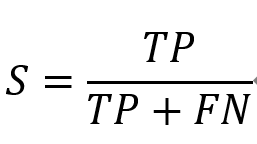

- Specificity，特效性，又称真负率，模型正确识别为负0的对象占全部对象中实际为负的对象数量的比值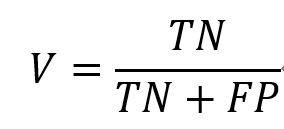

- Precision，精度：指模型正确识别为正的对象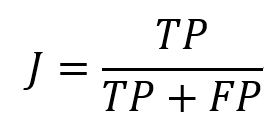占模型识别为正的对象数量的比值

- False Positive Rate：错正率，假阳率

- Negative Predictive  Value：负元正确率

- False Discovery  Value：正元错误率

实际应用中，可以选择地采用某些指标，不一定全要，关键看业务场景。

2、ROC曲线和AUC

** ROC曲线的定义**

ROC的全称是Receiver Operating Characteristic Curve，中文名字叫“受试者工作特征曲线” 。

有效比较分类模型的可视化工具。ROC曲线来源于信号检测理论，显示了给定模型的真阳率和假阳率False Positive Rate之间的比较评定。

这里在网上找了一个比较好的图样示例如下，

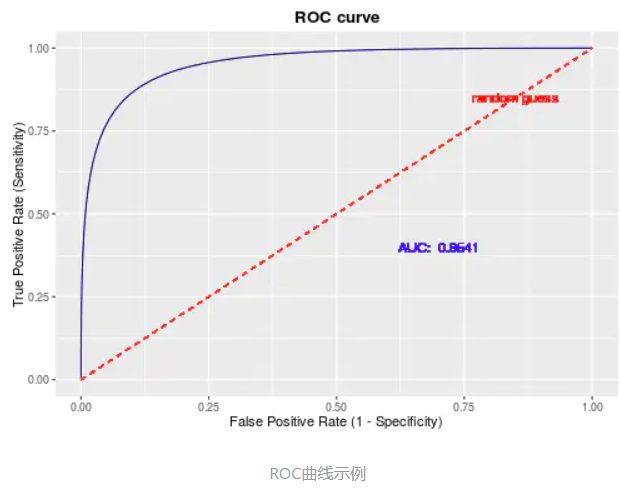

比如对于一个给定的二分类问题，通过对测试数据集的不同部分所显示的模型观察，可以正确识别1的比例和模型将0实例错误地识别为1的比例并进行分析，来比较不同模型的准确率并评定。

正阳率的增加是以假阳率的增加为代价，ROC曲线下的面积为AUC。

上图中，横轴是假阳率，纵轴是正阳率。ROC曲线离对角线越近，模型的准确率就越低。

简单地说，AUC越大，模型的预测效果越好。

由于大部分人工智能模型是所谓的评分模型，也就是直接的模型结果是类别的概率而非类别本身，因此，准确率，错误率等这种分类结果的评估指标并不能很好地评判模型效果。

而AUC则不同，可以全面地评价一个模型，因为它通过构造ROC曲线将所有可能的分类结果都综合考虑。

对角线代表辨别力等于0的一条线，也叫纯机遇线。

ROC曲线离纯机遇线越远，表明被试的辨别力越强。

辨别力不同的被试的ROC曲线也不同。

参考文献

- [意]朱塞佩.恰布罗，张雅仁等译，人民邮电出版社，matlab机器学习，2020年5月

- Matlab数据分析, 康海刚 段班祥 主编，机械工业出版社，2021年2月

- https://www.jianshu.com/p/2ca96fce7e81